# F-16A Level 2 Sizing Analysis — Class-Based Example

This live script performs a Fidelity Level 2 sizing pass for the F-16A example using the toolkit classes supplied with the project. This version captures the W_TO value returned by SizingClassLevel2.size_aircraft().

Main objects used: * AircraftDesign * GeometryLevel2 * AeroLevel2 * PropulsionLevel2 * WeightLevel2 * MissionAnalysisLevel2 * ConstraintAnalysisClass * Requirements * SizingClassLevel2

The script assumes the corresponding class files, import utilities, design workbook, requirements table, constraints table, and mission profile are on the MATLAB path.

clear; close all;

## Project setup

Set this to the folder containing your classes, import utilities, design spreadsheet/workbook, requirements file, constraints file, and mission data.

projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

## Create the aircraft design object

AircraftDesign is the project-level object. It imports the design geometry, fuselage data, propulsion data, weight data, general aircraft data, and requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);

## Build the Level 2 analysis objects

Level 2 uses more design geometry than Level 1. GeometryLevel2 computes component wetted areas from exposed planform/body estimates, AeroLevel2 uses equivalent skin-friction and wetted-area buildup for CD0, PropulsionLevel2 estimates installed TSFC from Mach/altitude/engine type, and WeightLevel2 uses a more parameterized empty-weight regression.

## Geometry

geometry_obj     = F16GeometryLevel2(design);

## Aerodynamics

aero_obj         = F16AeroLevel2(geometry_obj);
aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt.

## Propulsion

propulsion_obj   = F16PropulsionLevel2(design);

## Weight

weight_obj       = F16WeightLevel2(design, geometry_obj);

## Mission

mission_obj      = F16MissionAnalysisLevel2(missionName);

## Constraints

We require constraints like "optimum wing-loading" and "minimum T/W" for sizing computations. So we'll initialize them, here.

constraint_obj   = F16ConstraintAnalysis();

% Need to update the aerodynamic constraints for each given constraint
% (altitude, mach number)

% Get table of state vectors (mach number, altitude) for each constraint
% (constraint name)
constraints_table = Import_Constraints(constraintsName);

constraints_length = length(constraints_table.Altitude_ft_)

constraints_length = 8


% Load up miscellaneous constraints
beta = constraints_table.W_Wto;
n = constraints_table.n;
mu = constraints_table.SurfaceFrictionCoefficient_mu_;
Ps = constraints_table.PS_ft_s_;
distance = constraints_table.Distance_ft_;

% Clean up inputs before things get messy
Ps(isnan(Ps)==1)=0;
n(isnan(n)==1)=0;
distance(isnan(distance)==1)=0;
mu(isnan(mu)==1)=0;


% Get the Mach number and altitude
M = constraints_table.MachNumber;
h_alt = constraints_table.Altitude_ft_;
state_vector = [M, h_alt];

% Set up geometry stuff
AR = geometry_obj.mainwings.AR;
LE_sweep_deg = geometry_obj.mainwings.LE_sweep;
Cf = aero_obj.Cf; % Compute this
S_wet = geometry_obj.get_design_S_wet();
S_ref = geometry_obj.mainwings.S_ref;
e_osw = aero_obj.e_osw;
T_SL_dry = propulsion_obj.T_SL_dry;
T_SL_wet = propulsion_obj.T_SL_wet;
gamma = 1.4;

W_S = constraint_obj.Wto_S_range;

% Get density at sea level
[T, a, P, rho_SL] = atmosisa(0);

% Convert rho_SL to slugs
rho_SL = rho_SL*0.00194032033; % Convert from kg/m^3 -> imperial units

for i=1:constraints_length
     current_constraint = constraints_table.Row{i}
     AB_percent = constraints_table.AB_(i);

     M = state_vector(i,1);
     h_alt = state_vector(i,2);
     newstatevector = [M, h_alt];

     % Get density at current altitude
     [T, a, P, rho] = atmosisa(h_alt*0.3048);

     % Convert rho to slugs
     rho = rho*0.00194032033; % Convert from kg/m^3 -> imperial units

     % Convert a to ft/s
     a = a*3.2808399;

     if isnan(AB_percent)==true
          AB_percent = 1.0;
     elseif (AB_percent > 1.0)
          AB_percent = AB_percent/100;
     elseif (0.0 < AB_percent < 1.0)
          % Do nothing
     else
          error("Error handler.") % Just in case something weird happens.
     end

     % This thing breaks for "takeoff" and "landing" segments.
     % Need takeoff/landing velocity for computations (CD0, alpha,
     % alpha_dry/wet). To get that velocity, I need the weight. To get the
     % weight, I need the velocity... I can start with the guess weight.
     if (current_constraint == "Takeoff")
          % Do takeoff calculations
          % V = 168; % Hardcoded takeoff velocity (ft/s)
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_TO, rho)
               V_TO = 1.2*V_stall;
               M_TO = V_TO./a;

               takeoff_statevector = [M_TO, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_TO, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(takeoff_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(takeoff_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               aero_constraints_takeoff(k, :) = [e_osw, K1, K2, CD0, V_TO, q];
               thrust_constraints_takeoff(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_takeoff = aero_constraints_takeoff(:,1);
          K1_takeoff = aero_constraints_takeoff(:,2);
          K2_takeoff = aero_constraints_takeoff(:,3);
          CD0_takeoff = aero_constraints_takeoff(:,4);
          V_takeoff = aero_constraints_takeoff(:,5);
          q_takeoff = aero_constraints_takeoff(:,6);

          alpha_takeoff = thrust_constraints_takeoff(:,1);
          alpha_dry_takeoff = thrust_constraints_takeoff(:,2);
          alpha_wet_takeoff = thrust_constraints_takeoff(:,3);
     elseif (current_constraint == "Landing")
          % Do landing calculations
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_Land, rho)
               V_Land = 1.3*V_stall;
               M_Land = V_Land./a;

               landing_statevector = [M_Land, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_Land, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(landing_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(landing_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               % thrust_constraints(i, :) = [0, 0, 0];
               % aero_constraints(i, :) = [0, 0, 0, 0, 0, 0];
               aero_constraints_landing(k, :) = [e_osw, K1, K2, CD0, V_Land, q];
               thrust_constraints_landing(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_landing = aero_constraints_landing(:,1);
          K1_landing = aero_constraints_landing(:,2);
          K2_landing = aero_constraints_landing(:,3);
          CD0_landing = aero_constraints_landing(:,4);
          V_land = aero_constraints_landing(:,5);
          q_land = aero_constraints_landing(:,6);

          alpha_landing = thrust_constraints_landing(:,1);
          alpha_dry_landing = thrust_constraints_landing(:,2);
          alpha_wet_landing = thrust_constraints_landing(:,3);
     else
          % Compute thrust constraints (alpha_dry, alpha_wet, alpha)
          [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(newstatevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

          % Compute thrust at altitude (sanity check)
          T_alt_wet = PropulsionUtils.thrust_from_lapse(alpha_wet, T_SL_wet)
          T_alt_dry = PropulsionUtils.thrust_from_lapse(alpha_dry, T_SL_dry)

          thrust_constraints(i, :) = [alpha, alpha_dry, alpha_wet];

          [K1, K2] = aero_obj.get_K(AR, e_osw, M, LE_sweep_deg, aero_obj.CL_minD)
          [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints([M, h_alt], e_osw, Cf, S_wet, S_ref)
          aero_constraints(i, :) = [e_osw, K1, K2, CD0, V, q];
     end
end

current_constraint = 'Max Mach'

alpha = 0.5494

alpha_dry = 0.3089

alpha_wet = 0.5494

T_alt_wet = 1.3060e+04

T_alt_dry = 4.6332e+03

K1 = 0.2760

K2 = 0

e_osw = 0.9086

CD0 = 0.0168

V = 1.5496e+03

q = 850.6819

current_constraint = 'Cruise'

alpha = 0.1391

alpha_dry = 0.2204

alpha_wet = 0.3674

T_alt_wet = 8.7330e+03

T_alt_dry = 3.3066e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0168

V = 842.5695

q = 251.5161

current_constraint = 'Max Alt'

alpha = 0.1875

alpha_dry = 0.1125

alpha_wet = 0.1875

T_alt_wet = 4.4559e+03

T_alt_dry = 1.6871e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0168

V = 842.2259

q = 128.3319

current_constraint = 'Combat Subsonic'

alpha = 0.7526

alpha_dry = 0.4516

alpha_wet = 0.7526

T_alt_wet = 1.7890e+04

T_alt_dry = 6.7738e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0168

V = 902.0595

q = 515.2562

current_constraint = 'Combat Supersonic'

alpha = 0.6007

alpha_dry = 0.3546

alpha_wet = 0.6007

T_alt_wet = 1.4278e+04

T_alt_dry = 5.3187e+03

K1 = 0.2261

K2 = 0

e_osw = 0.9086

CD0 = 0.0168

V = 1.3559e+03

q = 651.3034

current_constraint = 'Excess Power'

alpha = 0.8608

alpha_dry = 0.5028

alpha_wet = 0.8608

T_alt_wet = 2.0462e+04

T_alt_dry = 7.5426e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0168

V = 937.3253

q = 771.0782

current_constraint = 'Takeoff'

V_stall = 114.8566

e_osw = 0.9086

CD0 = 0.0168

V = 137.8280

q = 22.5764

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 133.4513

e_osw = 0.9086

CD0 = 0.0168

V = 160.1416

q = 30.4781

alpha = 0.9999

alpha_dry = 0.5992

alpha_wet = 0.9999

V_stall = 149.7547

e_osw = 0.9086

CD0 = 0.0168

V = 179.7057

q = 38.3798

alpha = 0.9999

alpha_dry = 0.5990

alpha_wet = 0.9999

V_stall = 164.4497

e_osw = 0.9086

CD0 = 0.0168

V = 197.3396

q = 46.2816

alpha = 0.9998

alpha_dry = 0.5988

alpha_wet = 0.9998

V_stall = 177.9351

e_osw = 0.9086

CD0 = 0.0168

V = 213.5221

q = 54.1833

alpha = 0.9998

alpha_dry = 0.5985

alpha_wet = 0.9998

V_stall = 190.4682

e_osw = 0.9086

CD0 = 0.0168

V = 228.5618

q = 62.0850

alpha = 0.9997

alpha_dry = 0.5983

alpha_wet = 0.9997

V_stall = 202.2260

e_osw = 0.9086

CD0 = 0.0168

V = 242.6712

q = 69.9868

alpha = 0.9996

alpha_dry = 0.5980

alpha_wet = 0.9996

V_stall = 213.3367

e_osw = 0.9086

CD0 = 0.0168

V = 256.0041

q = 77.8885

alpha = 0.9995

alpha_dry = 0.5978

alpha_wet = 0.9995

V_stall = 223.8968

e_osw = 0.9086

CD0 = 0.0168

V = 268.6761

q = 85.7902

alpha = 0.9994

alpha_dry = 0.5975

alpha_wet = 0.9994

V_stall = 233.9807

e_osw = 0.9086

CD0 = 0.0168

V = 280.7769

q = 93.6919

alpha = 0.9993

alpha_dry = 0.5972

alpha_wet = 0.9993

V_stall = 243.6477

e_osw = 0.9086

CD0 = 0.0168

V = 292.3772

q = 101.5937

alpha = 0.9992

alpha_dry = 0.5969

alpha_wet = 0.9992

V_stall = 252.9455

e_osw = 0.9086

CD0 = 0.0168

V = 303.5346

q = 109.4954

alpha = 0.9990

alpha_dry = 0.5967

alpha_wet = 0.9990

V_stall = 261.9134

e_osw = 0.9086

CD0 = 0.0168

V = 314.2961

q = 117.3971

alpha = 0.9989

alpha_dry = 0.5964

alpha_wet = 0.9989

V_stall = 270.5843

e_osw = 0.9086

CD0 = 0.0168

V = 324.7011

q = 125.2989

alpha = 0.9987

alpha_dry = 0.5961

alpha_wet = 0.9987

V_stall = 278.9858

e_osw = 0.9086

CD0 = 0.0168

V = 334.7829

q = 133.2006

alpha = 0.9986

alpha_dry = 0.5958

alpha_wet = 0.9986

V_stall = 287.1416

e_osw = 0.9086

CD0 = 0.0168

V = 344.5699

q = 141.1023

alpha = 0.9984

alpha_dry = 0.5954

alpha_wet = 0.9984

V_stall = 295.0720

e_osw = 0.9086

CD0 = 0.0168

V = 354.0864

q = 149.0041

alpha = 0.9982

alpha_dry = 0.5951

alpha_wet = 0.9982

V_stall = 302.7948

e_osw = 0.9086

CD0 = 0.0168

V = 363.3538

q = 156.9058

alpha = 0.9980

alpha_dry = 0.5948

alpha_wet = 0.9980

V_stall = 310.3255

e_osw = 0.9086

CD0 = 0.0168

V = 372.3906

q = 164.8075

alpha = 0.9978

alpha_dry = 0.5944

alpha_wet = 0.9978

V_stall = 317.6777

e_osw = 0.9086

CD0 = 0.0168

V = 381.2133

q = 172.7092

alpha = 0.9976

alpha_dry = 0.5941

alpha_wet = 0.9976

V_stall = 324.8636

e_osw = 0.9086

CD0 = 0.0168

V = 389.8363

q = 180.6110

alpha = 0.9973

alpha_dry = 0.5937

alpha_wet = 0.9973

current_constraint = 'Landing'

V_stall = 108.6374

e_osw = 0.9086

CD0 = 0.0168

V = 141.2286

q = 23.7042

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 126.2252

e_osw = 0.9086

CD0 = 0.0168

V = 164.0928

q = 32.0006

alpha = 0.9999

alpha_dry = 0.5992

alpha_wet = 0.9999

V_stall = 141.6458

e_osw = 0.9086

CD0 = 0.0168

V = 184.1395

q = 40.2971

alpha = 0.9999

alpha_dry = 0.5989

alpha_wet = 0.9999

V_stall = 155.5450

e_osw = 0.9086

CD0 = 0.0168

V = 202.2085

q = 48.5935

alpha = 0.9998

alpha_dry = 0.5987

alpha_wet = 0.9998

V_stall = 168.3003

e_osw = 0.9086

CD0 = 0.0168

V = 218.7903

q = 56.8900

alpha = 0.9997

alpha_dry = 0.5984

alpha_wet = 0.9997

V_stall = 180.1547

e_osw = 0.9086

CD0 = 0.0168

V = 234.2011

q = 65.1864

alpha = 0.9997

alpha_dry = 0.5982

alpha_wet = 0.9997

V_stall = 191.2758

e_osw = 0.9086

CD0 = 0.0168

V = 248.6585

q = 73.4829

alpha = 0.9996

alpha_dry = 0.5979

alpha_wet = 0.9996

V_stall = 201.7849

e_osw = 0.9086

CD0 = 0.0168

V = 262.3204

q = 81.7794

alpha = 0.9995

alpha_dry = 0.5976

alpha_wet = 0.9995

V_stall = 211.7732

e_osw = 0.9086

CD0 = 0.0168

V = 275.3051

q = 90.0758

alpha = 0.9993

alpha_dry = 0.5974

alpha_wet = 0.9993

V_stall = 221.3111

e_osw = 0.9086

CD0 = 0.0168

V = 287.7044

q = 98.3723

alpha = 0.9992

alpha_dry = 0.5971

alpha_wet = 0.9992

V_stall = 230.4546

e_osw = 0.9086

CD0 = 0.0168

V = 299.5910

q = 106.6687

alpha = 0.9991

alpha_dry = 0.5968

alpha_wet = 0.9991

V_stall = 239.2490

e_osw = 0.9086

CD0 = 0.0168

V = 311.0236

q = 114.9652

alpha = 0.9989

alpha_dry = 0.5965

alpha_wet = 0.9989

V_stall = 247.7313

e_osw = 0.9086

CD0 = 0.0168

V = 322.0507

q = 123.2616

alpha = 0.9988

alpha_dry = 0.5961

alpha_wet = 0.9988

V_stall = 255.9326

e_osw = 0.9086

CD0 = 0.0168

V = 332.7124

q = 131.5581

alpha = 0.9986

alpha_dry = 0.5958

alpha_wet = 0.9986

V_stall = 263.8792

e_osw = 0.9086

CD0 = 0.0168

V = 343.0430

q = 139.8545

alpha = 0.9984

alpha_dry = 0.5955

alpha_wet = 0.9984

V_stall = 271.5934

e_osw = 0.9086

CD0 = 0.0168

V = 353.0714

q = 148.1510

alpha = 0.9982

alpha_dry = 0.5951

alpha_wet = 0.9982

V_stall = 279.0944

e_osw = 0.9086

CD0 = 0.0168

V = 362.8227

q = 156.4475

alpha = 0.9980

alpha_dry = 0.5948

alpha_wet = 0.9980

V_stall = 286.3991

e_osw = 0.9086

CD0 = 0.0168

V = 372.3188

q = 164.7439

alpha = 0.9978

alpha_dry = 0.5944

alpha_wet = 0.9978

V_stall = 293.5220

e_osw = 0.9086

CD0 = 0.0168

V = 381.5786

q = 173.0404

alpha = 0.9976

alpha_dry = 0.5941

alpha_wet = 0.9976

V_stall = 300.4761

e_osw = 0.9086

CD0 = 0.0168

V = 390.6189

q = 181.3368

alpha = 0.9973

alpha_dry = 0.5937

alpha_wet = 0.9973

V_stall = 307.2728

e_osw = 0.9086

CD0 = 0.0168

V = 399.4547

q = 189.6333

alpha = 0.9971

alpha_dry = 0.5933

alpha_wet = 0.9971


% Build tables for aero constraints
aero_constraints_table = array2table(aero_constraints, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

aero_constraints_table = 6×6 table
                          e_osw       K1           K2          CD0         V         q   
                         _______    _______    __________    ________    ______    ______
    Max Mach             0.90862    0.27603             0    0.016763    1549.6    850.68
    Cruise               0.90862    0.11677    -0.0066398    0.016763    842.57    251.52
    Max Alt              0.90862    0.11677    -0.0066398    0.016763    842.23    128.33
    Combat Subsonic      0.90862    0.11677    -0.0066398    0.016763    902.06    515.26
    Combat Supersonic    0.90862     0.2261             0    0.016763    1355.9     651.3
    Excess Power         0.90

e_osw = aero_constraints(:,1);
K1 = aero_constraints(:,2);
K2 = aero_constraints(:,3);
CD0 = aero_constraints(:,4);
V = aero_constraints(:,5);
q = aero_constraints(:,6);

% Build table for thrust constraints
thrust_constraints_table = array2table(thrust_constraints, "VariableNames",{'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

thrust_constraints_table = 6×3 table
                          alpha     alpha_dry    alpha_wet
                         _______    _________    _________
    Max Mach             0.54943     0.30888      0.54943 
    Cruise               0.13911     0.22044       0.3674 
    Max Alt              0.18746     0.11247      0.18746 
    Combat Subsonic      0.75265     0.45159      0.75265 
    Combat Supersonic    0.60067     0.35458      0.60067 
    Excess Power         0.86082     0.50284      0.86082 

alpha = thrust_constraints(:,1);
alpha_dry = thrust_constraints(:,2);
alpha_wet = thrust_constraints(:,3);

% Make all constraint arrays the same size as the imported arrays (beta, n,
% Ps, etc).


% Compute T/W and wing loading stuff for all constraints
TW_table = constraint_obj.createThrustLoadingTable(aero_constraints_table, beta, alpha, n, q, V, CD0, K1, Ps, W_S)

TW_table =     1.3073    0.9742    0.7796    0.6526    0.5637    0.4982    0.4483    0.4091    0.3778    0.3524    0.3314    0.3139    0.2993    0.2869    0.2764    0.2674    0.2597    0.2532    0.2476    0.2428    0.2387
    1.5695    1.1955    0.9833    0.8500    0.7611    0.6997    0.6563    0.6257    0.6041    0.5894    0.5799    0.5745    0.5724    0.5729    0.5756    0.5802    0.5862    0.5936    0.6020    0.6114    0.6217
    0.6524    0.5311    0.4711    0.4410    0.4277    0.4247    0.4287    0.4374    0.4496    0.4644    0.4811    0.4994    0.5190    0.5395    0.5609    0.5829    0.6056    0.6287    0.6522    0.6761    0.7003
    0.6725    0.5583    0.5053    0.4822    0.4760    0.4801    0.4911    0.5069    0.5261    0.5479    0.5717    0.5970    0.6236    0.6512    0.6796    0.7087    0.7384    0.7686    0.7992    0.8301    0.8614
    0.9271    0.6979    0.5658    0.4809    0.4227    0.3809    0.3500    0.3267    0.3088    0.2951    0.2845    0.2763    0.2701    0.2655    0



% Takeoff and landing analysis
% CALCULATIONS

T_Wto_takeoff = ConstraintAnalysisClass.takeoff_constraint(W_S, 1.2, beta(7), alpha_takeoff', rho, aero_obj.CL_max_TO, distance(7), CD0_takeoff(7), mu(7))

T_Wto_takeoff =     0.1130    0.1388    0.1647    0.1905    0.2164    0.2422    0.2681    0.2939    0.3198    0.3457    0.3716    0.3975    0.4234    0.4493    0.4753    0.5012    0.5272    0.5532    0.5792    0.6052    0.6312


Wto_S_Landing = ConstraintAnalysisClass.landing_constraint(distance(8), beta(8), rho, aero_obj.CL_max_Land, CD0_landing(8), mu(8))

Wto_S_Landing = 131.5660




% Package the aero and thrust results into a table format to use the
% pre-existing graph functions.
new_constraints_array = [aero_constraints, thrust_constraints];
new_constraints_table = array2table(new_constraints_array, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q', 'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

new_constraints_table = 6×9 table
                          e_osw       K1           K2          CD0         V         q        alpha     alpha_dry    alpha_wet
                         _______    _______    __________    ________    ______    ______    _______    _________    _________
    Max Mach             0.90862    0.27603             0    0.016763    1549.6    850.68    0.54943     0.30888      0.54943 
    Cruise               0.90862    0.11677    -0.0066398    0.016763    842.57    251.52    0.13911     0.22044       0.3674 
    Max Alt              0.90862    0.11677    -0.0066398    0.016763    842.23    128.33    0.18746 


% Trim takeoff and landing from constraints table
% constraints_table = [constraints_table, new_constraints_table]

% Get optimal wing loading and T/W
[constraint_obj.optimal_WS, constraint_obj.min_TW] = constraint_obj.solveOptimalPoint(TW_table, T_Wto_takeoff, W_S)

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 118
                min_TW: 0.7016
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [1.5695 1.1955 1.0040 0.9296 0.8772 0.8383 0.8085 0.7849 0.7659 0.7502 0.7372 0.7261 0.7167 0.7086 0.7016 0.7087 0.7384 0.7686 0.7992 0.8301 0.8614]
     constraints_table: []
    constraints_struct: []

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 118
                min_TW: 0.7016
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [1.5695 1.1955 1.0040 0.9296 0.8772 0.8383 0.8085 0.7849 0.7659 0.7502 0.7372 0.7261 0.7167 0.7086 0.7016 0.7087 0.7384 0.7686 0.7992 0.8301 0.8614]
     constraints_table: []
    constraints_struct: []

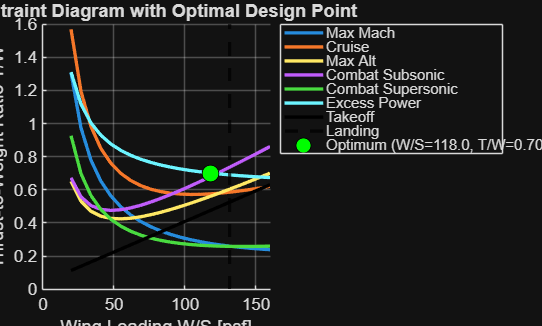


constraint_obj.plotConstraintDiagram(W_S, TW_table, T_Wto_takeoff, Wto_S_Landing, constraint_obj.optimal_WS, constraint_obj.min_TW, {constraints_table.Row{:}})

## Requirements

requirements_obj = Requirements(design);

## Sizing

sizing_obj       = F16SizingLevel2();

## Run the project sizing class

This calls your SizingClassLevel3 method directly and captures the returned takeoff gross weight. The sizing class still displays its internal iteration table. A persistent trace is reconstructed in the next section for plots and reporting.

results_table = sizing_obj.compute_TOGW( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);


## Synchronize object properties used by the plots

% Keep the sizing table available through both the returned variable and the sizing object.
if istable(results_table)
    sizing_obj.results_table = results_table;
else
    results_table = sizing_obj.results_table;
end

assert(istable(results_table) && height(results_table) > 0, ...
    "F16SizingLevel2.size_aircraft must return/populate a non-empty results_table.");

% Synchronize the existing objects to the final sizing-row values before plotting.
finalSizingRow = results_table(end, :);
weight_obj.W_TO = finalSizingRow.WTO_new;
weight_obj.W_fixed = finalSizingRow.W_fixed;
weight_obj.OEW = finalSizingRow.Empty_weight;
weight_obj.OEW_frac = finalSizingRow.Empty_weight_fraction;
weight_obj.total_fuel_used = finalSizingRow.WTO_new - finalSizingRow.W_fixed - finalSizingRow.Empty_weight;
weight_obj.fuel_fraction = finalSizingRow.Fuel_fraction;

geometry_obj.mainwings.S_ref = finalSizingRow.S_ref_w;
geometry_obj.design.S_wet = finalSizingRow.S_wet_design;

propulsion_obj.T0 = constraint_obj.min_TW * weight_obj.W_TO;

% Store per-segment fuel burn in the existing mission object property.
mission_obj.mission_fuel = buildLevel2MissionFuelTable( ...
    mission_obj, ...
    propulsion_obj, ...
    design, ...
    geometry_obj, ...
    constraint_obj, ...
    weight_obj, ...
    aero_obj);

% Match the total fuel property to the plotted segment table.
weight_obj.total_fuel_used = sum(mission_obj.mission_fuel.FuelUsed_lbf, "omitnan");
weight_obj.fuel_fraction = weight_obj.total_fuel_used * 1.06 / weight_obj.W_TO;

% Build aerodynamic coefficient data for every flight-capable mission segment.
aeroMissionCoefficients = buildLevel2AeroCoefficientTable( ...
    aero_obj, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj);

% Keep declared AeroLevel2 scalar properties synchronized to cruise when available.
cruiseIdx = find(aeroMissionCoefficients.Segment == "Cruise", 1);
if isempty(cruiseIdx)
    cruiseIdx = 1;
end
if ~isempty(cruiseIdx) && height(aeroMissionCoefficients) >= cruiseIdx
    aero_obj.CD0 = aeroMissionCoefficients.CD0(cruiseIdx);
    aero_obj.K   = aeroMissionCoefficients.K(cruiseIdx);
end

% Build final component/mission weight table for plotting and saving.
componentWeightBreakdown = buildLevel2ComponentWeightBreakdown(weight_obj);


## Plot gross-weight convergence

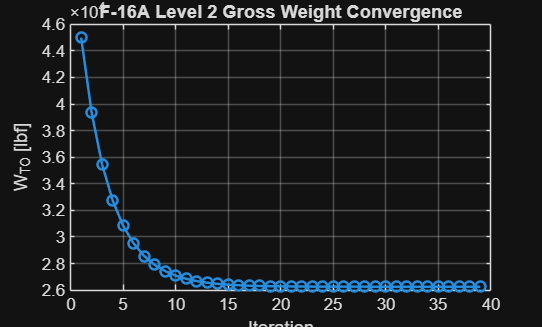

figure('Name', 'Level 2 Gross Weight Convergence');
iterationIdx = 1:height(results_table);
plot(iterationIdx, results_table.WTO, '-o', 'LineWidth', 1.5); grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 2 Gross Weight Convergence');

## Plot closure error

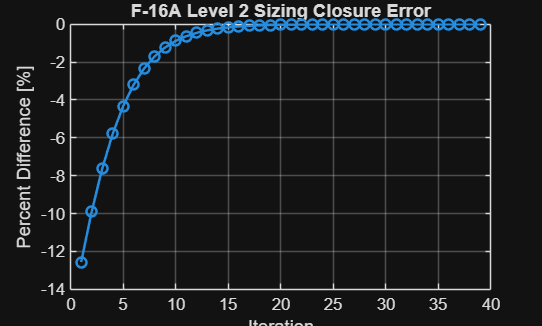

figure('Name', 'Level 2 Closure Error');
iterationIdx = 1:height(results_table);
plot(iterationIdx, results_table.Percent_Diff, '-o', 'LineWidth', 1.5); grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 2 Sizing Closure Error');

## Plot component weight breakdown

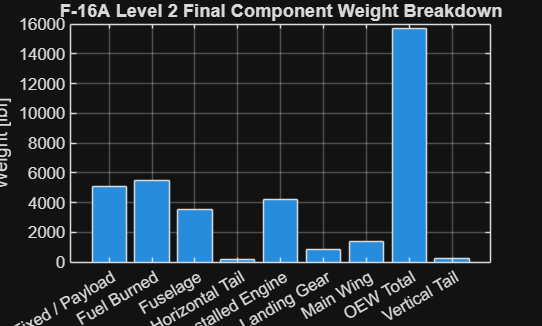

figure('Name', 'Level 2 Final Component Weight Breakdown');
bar(categorical(componentWeightBreakdown.Component), componentWeightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 2 Final Component Weight Breakdown');

## Plot fuel burned at each mission segment

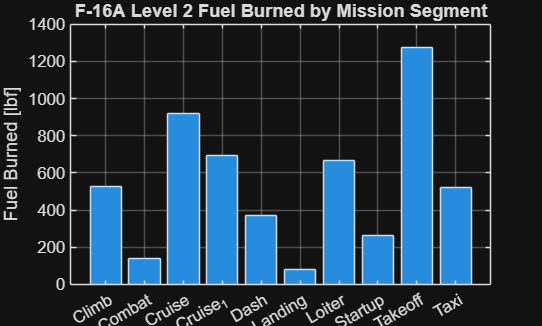

figure('Name', 'Level 2 Fuel Burned by Mission Segment');
bar(categorical(mission_obj.mission_fuel.Segment), mission_obj.mission_fuel.FuelUsed_lbf);
grid on;
ylabel('Fuel Burned [lbf]');
title('F-16A Level 2 Fuel Burned by Mission Segment');

## Plot aerodynamic coefficients at each mission segment

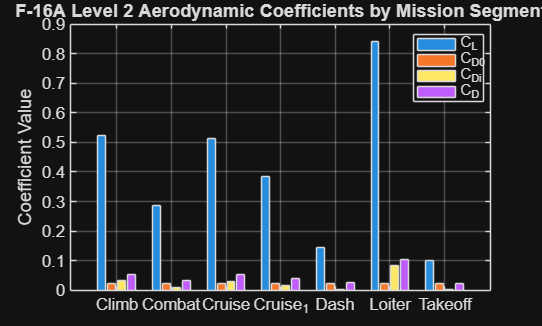

figure('Name', 'Level 2 Aerodynamic Coefficients by Mission Segment');
bar(categorical(aeroMissionCoefficients.Segment), ...
    [aeroMissionCoefficients.CL, ...
     aeroMissionCoefficients.CD0, ...
     aeroMissionCoefficients.CDi, ...
     aeroMissionCoefficients.CD]);
grid on;
ylabel('Coefficient Value');
title('F-16A Level 2 Aerodynamic Coefficients by Mission Segment');
legend({'C_L', 'C_{D0}', 'C_{Di}', 'C_D'}, 'Location', 'best');

## Save results into the AircraftDesign object

AircraftDesign is a handle class, so these assignments persist on the design object during this MATLAB session.

design.WeightResults.Level2SizingTable = results_table;
design.WeightResults.W_TO              = weight_obj.W_TO;
design.WeightResults.OEW               = weight_obj.OEW;
design.WeightResults.FuelUsed          = weight_obj.total_fuel_used;
design.WeightResults.FixedWeight       = weight_obj.W_fixed;
design.WeightResults.Level2MissionFuel = mission_obj.mission_fuel;
design.WeightResults.Level2ComponentWeights = componentWeightBreakdown;

design.AeroResults.Level2.Cf = aero_obj.Cf;
design.AeroResults.Level2.e_osw = aero_obj.e_osw;
design.AeroResults.Level2.CD0 = aero_obj.CD0;
design.AeroResults.Level2.K = aero_obj.K;
design.AeroResults.Level2.MissionCoefficients = aeroMissionCoefficients;

design.PropulsionResults.Level2.T0 = propulsion_obj.T0;

fprintf("\nSaved Level 2 sizing/plot data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.\n");


Saved Level 2 sizing/plot data back into design.WeightResults, design.AeroResults, and design.PropulsionResults.


## Local helper functions

function value = getFieldOrNaN(s, fieldName)
    value = NaN;

    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    end

    if iscell(value) && numel(value) == 1
        value = value{1};
    end

    if ~(isscalar(value) && isnumeric(value) && isfinite(value))
        value = NaN;
    end
end

function txt = getFieldText(s, fieldName, defaultText)
    txt = string(defaultText);

    if isstruct(s) && isfield(s, fieldName)
        raw = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        raw = s.(fieldName);
    else
        return
    end

    if iscell(raw)
        raw = raw{1};
    end

    raw = string(raw);
    raw = replace(raw, '"', '');
    raw = strtrim(raw);

    if strlength(raw) > 0 && ~ismissing(raw)
        txt = raw;
    end
end

function normalizedName = normalizeSegmentName(rawName)
    normalizedName = erase(string(rawName), '_');
    normalizedName = erase(normalizedName, {'0','1','2','3','4','5','6','7','8','9'});
end

function missionFuel = buildLevel2MissionFuelTable(mission_obj, propulsion_obj, design, geometry_obj, constraint_obj, weight_obj, aero_obj)
    segmentNames = fieldnames(mission_obj.missiondata);

    W_TO = weight_obj.W_TO;
    W_S = constraint_obj.optimal_WS;
    S_ref = geometry_obj.mainwings.S_ref;
    S_wet_aircraft = geometry_obj.design.S_wet;
    AR = geometry_obj.mainwings.AR;
    T0 = propulsion_obj.T0;
    engine_type = design.propulsion_type;

    W_segments = nan(1, numel(segmentNames));
    fuelBurned = nan(1, numel(segmentNames));
    W_segments(1) = W_TO;

    segment = strings(0,1);
    W_in = nan(0,1);
    W_out = nan(0,1);
    fuel = nan(0,1);
    powerSetting = strings(0,1);
    TSFC_1_per_s = nan(0,1);

    for i = 1:numel(segmentNames)
        rawName = string(segmentNames{i});
        currentsegment = normalizeSegmentName(rawName);

        if currentsegment == "meta"
            break
        end

        segData = mission_obj.missiondata.(segmentNames{i});
        M = getFieldOrNaN(segData, 'MachNumber');
        alt = getFieldOrNaN(segData, 'Altitudeft');
        q = getFieldOrNaN(segData, 'qlbfft2');
        a = getFieldOrNaN(segData, 'afts');
        CD0 = aero_obj.get_design_CD0(aero_obj.Cf, S_wet_aircraft, S_ref);

        dryOrWet = getFieldText(segData, 'DryOrWet', 'Dry');
        if strcmpi(dryOrWet, "Wet")
            pwr = "max";
        else
            pwr = "mil";
        end

        if isfinite(M) && isfinite(alt)
            TSFC = propulsion_obj.get_TSFC(engine_type, [M, alt], pwr);
        else
            TSFC = NaN;
        end

        if currentsegment == "Startup"
            win = W_segments(i);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_startup(W_segments(i));
        elseif currentsegment == "Taxi"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_taxi(W_segments(i-1));
        elseif currentsegment == "Takeoff"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_takeoff(W_segments(i-1));
        elseif currentsegment == "Climb"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_climb(W_TO, W_segments(i-1), M, S_ref, CD0, mission_obj.missiondata.Cruise.e, AR, TSFC, alt, T0);
        elseif currentsegment == "Cruise"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_cruise(W_segments(i-1), W_S, TSFC, mission_obj.missiondata.Cruise.Rangeft, M, a, q, CD0, mission_obj.missiondata.Cruise.e, AR, W_TO, S_ref);
        elseif currentsegment == "Dash"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_dash(W_segments(i-1), W_S, W_TO, q, CD0, mission_obj.missiondata.Dash.e, AR, TSFC, mission_obj.missiondata.Dash.Rangeft, M * a);
        elseif currentsegment == "Combat"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_combat(W_segments(i-1), mission_obj.missiondata.Combat.Timemin, TSFC, mission_obj.missiondata.Combat.PayloadDroplbf, CD0, mission_obj.missiondata.Combat.e, AR, W_TO, q, W_S);
        elseif currentsegment == "Loiter"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_loiter(W_TO, W_segments(i-1), W_S, q, CD0, mission_obj.missiondata.Loiter.e, AR, mission_obj.missiondata.Loiter.Timemin, TSFC);
        elseif currentsegment == "Landing"
            win = W_segments(i-1);
            [W_segments(i), fuelBurned(i)] = MissionAnalysisLevel2.segment_landing(W_segments(i-1), W_TO);
        elseif currentsegment == "Descent"
            continue
        else
            error("Couldn't identify mission segment name: %s", rawName);
        end

        segment(end+1,1) = rawName;
        W_in(end+1,1) = win;
        W_out(end+1,1) = W_segments(i);
        fuel(end+1,1) = fuelBurned(i);
        powerSetting(end+1,1) = pwr;
        TSFC_1_per_s(end+1,1) = TSFC;
    end

    missionFuel = table(segment, W_in, W_out, fuel, powerSetting, TSFC_1_per_s, ...
        'VariableNames', {'Segment', 'W_in_lbf', 'W_out_lbf', 'FuelUsed_lbf', 'PowerSetting', 'TSFC_1_per_s'});
end

function aeroMission = buildLevel2AeroCoefficientTable(aero_obj, geometry_obj, mission_obj, weight_obj)
    segmentNames = fieldnames(mission_obj.missiondata);

    segment = strings(0,1);
    mach = nan(0,1);
    altitude = nan(0,1);
    W_in = nan(0,1);
    CL = nan(0,1);
    CD0 = nan(0,1);
    CDi = nan(0,1);
    CD = nan(0,1);
    K = nan(0,1);
    drag = nan(0,1);

    S_ref = geometry_obj.mainwings.S_ref;

    for i = 1:numel(segmentNames)
        rawName = string(segmentNames{i});
        segData = mission_obj.missiondata.(segmentNames{i});

        M = getFieldOrNaN(segData, 'MachNumber');
        h_ft = getFieldOrNaN(segData, 'Altitudeft');

        if ~isfinite(M) || ~isfinite(h_ft) || M <= 0
            continue
        end

        W_seg = getSegmentInputWeight(mission_obj.mission_fuel, rawName, weight_obj.W_TO);
        state_input = [M, h_ft, 0, W_seg];

        dragResults = aero_obj.get_design_drag(geometry_obj, state_input);
        q = getFieldOrNaN(segData, 'qlbfft2');
        if ~isfinite(q) || q <= 0
            q = AeroUtils.compute_q(state_input);
        end

        CL_seg = computeCLForPlot(W_seg, q, S_ref);
        CD0_seg = dragResults.CD0;
        CD_seg = dragResults.CD;
        K_seg = aero_obj.K;
        CDi_seg = max(CD_seg - CD0_seg, 0);

        segment(end+1,1) = rawName;
        mach(end+1,1) = M;
        altitude(end+1,1) = h_ft;
        W_in(end+1,1) = W_seg;
        CL(end+1,1) = CL_seg;
        CD0(end+1,1) = CD0_seg;
        CDi(end+1,1) = CDi_seg;
        CD(end+1,1) = CD_seg;
        K(end+1,1) = K_seg;
        drag(end+1,1) = dragResults.D;
    end

    aeroMission = table(segment, mach, altitude, W_in, CL, CD0, CDi, CD, K, drag, ...
        'VariableNames', {'Segment', 'Mach', 'Altitude_ft', 'W_in_lbf', 'CL', 'CD0', 'CDi', 'CD', 'K', 'Drag_lbf'});
end

function CL = computeCLForPlot(W, q, S_ref)
    try
        CL = AeroUtils.compute_CL(W, q, S_ref);
    catch
        CL = W / (q * S_ref);
    end
end

function W_seg = getSegmentInputWeight(missionFuel, segmentName, defaultWeight)
    W_seg = defaultWeight;

    if istable(missionFuel) && any(strcmp(missionFuel.Properties.VariableNames, 'Segment')) && any(strcmp(missionFuel.Properties.VariableNames, 'W_in_lbf'))
        names = string(missionFuel.Segment);
        idx = find(names == segmentName, 1);

        if isempty(idx)
            idx = find(normalizeSegmentName(names) == normalizeSegmentName(segmentName), 1);
        end

        if ~isempty(idx) && isfinite(missionFuel.W_in_lbf(idx))
            W_seg = missionFuel.W_in_lbf(idx);
        end
    end
end

function componentWeightBreakdown = buildLevel2ComponentWeightBreakdown(weight_obj)
    component = [ ...
        "Main Wing"; ...
        "Horizontal Tail"; ...
        "Vertical Tail"; ...
        "Fuselage"; ...
        "Landing Gear"; ...
        "Installed Engine"; ...
        "Fuel Burned"; ...
        "Fixed / Payload"; ...
        "OEW Total"];

    weight_lbf = [ ...
        safeScalar(weight_obj.wings); ...
        safeScalar(weight_obj.HT); ...
        safeScalar(weight_obj.VT); ...
        safeScalar(weight_obj.fuselage); ...
        safeScalar(weight_obj.landinggear); ...
        safeScalar(weight_obj.engine); ...
        safeScalar(weight_obj.total_fuel_used); ...
        safeScalar(weight_obj.W_fixed); ...
        safeScalar(weight_obj.OEW)];

    componentWeightBreakdown = table(component, weight_lbf, ...
        'VariableNames', {'Component', 'Weight_lbf'});
end

function value = safeScalar(value)
    if isempty(value) || ~isscalar(value) || ~isnumeric(value) || ~isfinite(value)
        value = NaN;
    end
end

